# Figure displaying call examples across repertoire

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
GGPath = dir('/Users/elie/Google Drive*');
Path2Paper = fullfile(GGPath.folder, GGPath.name, 'My Drive', 'BatmanData', 'Deaf Paper');
% Path2Paper = fullfile(GGPath.folder, GGPath.name, 'Mon Drive', 'BatmanData', 'Deaf Paper');

Loading previous data

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls2.mat'), 'CallType', 'BatID','MPS_mic', 'MPS_mic_wf', 'MPS_mic_wt')
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'MicAudioGood','TmicAll7');
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'), 'MicFileNum', 'MicFileSampleID', 'OnSetOffsetSample', 'CallDate','Q1Mic_mean','Q3Mic_mean','Spect_psd', 'Spect_psdf', 'Spect_psd_biosound', 'Spect_psdf_biosound');
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);
load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFA_MaleAcGroup5.mat'), 'NPC_opt_M', 'PC_DF_males', 'EigenVec_DFA_M', 'MPS_mic_wf', 'IndWf', 'MPS_mic_wt')

Get color vectors ready

load(fullfile(LocalDataDir, 'Data4_DeafBats_IDCT.mat'))
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];

% Get the color vector ready for BatName, Sex and Deafness

try
    Path2RecordingTable = fullfile(GGPath.folder, GGPath.name,'My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
    [~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
catch ME
    Path2RecordingTable = fullfile(GGPath.folder, GGPath.name,'Mon Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
    [~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
end
    
   
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(size(BatName));
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
CBat = nan(length(BatID),3);
UCBatName = nan(length(BatName),3);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    CBat(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(bat,:),sum(contains(BatID,num2str(BatName(bat)))),1);
    UCBatName(bat,:) = ColorCode(bat,:);
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Female';
    end

end
USexDeaf = {'Deaf Male' 'Hearing Male' 'Deaf Female' 'Hearing Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);
BatName = BatName([1:7 10 8:9]);
BatSexDeaf = BatSexDeaf([1:7 10 8:9]);
UCBatName = UCBatName([1:7 10 8:9],:);
UCBatNameSexDeaf = ColorCode([2 2 2 3 3 3 1 1 6 6], :);

First restrict the MPS spectral frequency to 3 cycles/kHz and normalized all MPS

addpath(genpath('/Users/elie/Documents/CODE/GitHub/umapDistribution'))
IndWf = (MPS_mic_wf*1000)<=3; % Max Spectral frequency taken into account in cycles/kHz
NVoc = sum(MicAudioGood01);
MPS_mic_norm = cell(1,NVoc);
MPS_mic_diff = cell(1,NVoc);
MPS_mic_focus = cell(1,NVoc);
MPS_mic_mean = reshape(mean(MPS_mic(MicAudioGood01,:), 'omitnan')',length(MPS_mic_wf), length(MPS_mic_wt));
MPS_mic_logmean = reshape(mean(10*log10(MPS_mic(MicAudioGood01,:)), 'omitnan')',length(MPS_mic_wf), length(MPS_mic_wt));
IndMicAudioGood = find(MicAudioGood01);
for nn=1:NVoc
    vv=IndMicAudioGood(nn);
    MPS_local = reshape(MPS_mic(vv,:)',length(MPS_mic_wf), length(MPS_mic_wt));
    MPS_local = MPS_local(IndWf,:);
    MPS_mic_norm{nn} = reshape(MPS_local./MPS_mic_mean(IndWf,:), numel(MPS_local),1);
    MPS_mic_diff{nn} = reshape(10*log10(MPS_local)-MPS_mic_logmean(IndWf,:), numel(MPS_local),1);
    MPS_mic_focus{nn} = reshape(MPS_local, numel(MPS_local),1);
end
MPS_mic_norm = [MPS_mic_norm{:}]';
MPS_mic_diff = [MPS_mic_diff{:}]';
MPS_mic_focus = [MPS_mic_focus{:}]';

**Average MPS over all calls**

plot_mps(MPS_mic_mean, MPS_mic_wf(IndWf), MPS_mic_wt, 60,nan,1, [0 max(MPS_mic_wf(IndWf)*10^3)], [-150 150]);
title('Log Average Mic MPS over all calls')


plot_mps(MPS_mic_logmean, MPS_mic_wf(IndWf), MPS_mic_wt, 60,nan,0, [0 max(MPS_mic_wf(IndWf)*10^3)], [-150 150]);
title('Average log Mic MPS over all calls')

Identify representative examples of calls accross the bat repertoire

MicAudioGoodInd = find(MicAudioGood);
NumEx = 5; % number of examples per acoustic group
UAC = unique(TmicAll7);
MPSAcGr = cell(length(UAC),1);
for GR = 1:length(UAC)
    MicAudioGoodIndUac = MicAudioGoodInd(logical((TmicAll7==UAC(GR)) .* contains(SexDeaf(MicAudioGoodInd), 'H')));
    MPSInd = find((TmicAll7==UAC(GR)) .* contains(SexDeaf(MicAudioGoodInd), 'H'));
    MPSAcGr{GR} = reshape(mean(MPS_mic_norm(MPSInd,:),1), length(MPS_mic_wf(IndWf)),length(MPS_mic_wt));
    RandInd = randperm(length(MicAudioGoodIndUac));

    BatID_Examples = BatID(MicAudioGoodIndUac(RandInd));
    %     % Select Indices that correspond to two bats for each group
    %     BatID_DM = unique(BatID_DM_Examples);
    %     BatID_HM = unique(BatID_HM_Examples);
    %     RandInd_DM = nan(NumEx,1);
    %     RandInd_HM = RandInd_DM;
    %     for bb=1:length(BatID_DM)
    %         II = find(contains(BatID_DM_Examples,BatID_DM{bb}),2);
    %         RandInd_DM((bb*2-1) : bb*2) = RandInd(II);
    %         II = find(contains(BatID_HM_Examples,BatID_HM{bb}),2);
    %         RandInd_HM((bb*2-1) : bb*2) = RandInd(II);
    %     end

    Example.(sprintf('H%d',UAC(GR))).Spectro = cell(NumEx,1);
    Example.(sprintf('H%d',UAC(GR))).Fo = cell(NumEx,1);
    Example.(sprintf('H%d',UAC(GR))).To = cell(NumEx,1);
    Example.(sprintf('H%d',UAC(GR))).MPS = cell(NumEx,1);
    Example.(sprintf('H%d',UAC(GR))).MPS_norm = cell(NumEx,1);
    Example.(sprintf('H%d',UAC(GR))).Wf = cell(NumEx,1);
    Example.(sprintf('H%d',UAC(GR))).Wt = cell(NumEx,1);
    Example.(sprintf('H%d',UAC(GR))).Sound = cell(NumEx,1);
    Example.(sprintf('H%d',UAC(GR))).BatID = cell(NumEx,1);
    ii=1;
    while ii<=NumEx
        fprintf(1, 'AcGroup %d Example %d\n',UAC(GR),ii)
        Example.(sprintf('H%d',UAC(GR))).MPS{ii} = reshape(MPS_mic_focus(MPSInd(RandInd(ii)),:), length(MPS_mic_wf(IndWf)),length(MPS_mic_wt));
        Example.(sprintf('H%d',UAC(GR))).MPS_norm{ii} = reshape(MPS_mic_norm(MPSInd(RandInd(ii)),:), length(MPS_mic_wf(IndWf)),length(MPS_mic_wt));
        Example.(sprintf('H%d',UAC(GR))).MPS_diff{ii} = reshape(MPS_mic_diff(MPSInd(RandInd(ii)),:), length(MPS_mic_wf(IndWf)),length(MPS_mic_wt));
        Example.(sprintf('H%d',UAC(GR))).Wf{ii} = MPS_mic_wf(IndWf);
        Example.(sprintf('H%d',UAC(GR))).Wt{ii} = MPS_mic_wt;
        WhoFile = dir(fullfile(BaseDataDir, ['20' num2str(CallDate(MicAudioGoodIndUac(RandInd(ii))))], 'audiologgers', sprintf('DeSa_%s_*_%d_%d*200.pdf', num2str(CallDate(MicAudioGoodIndUac(RandInd(ii)))),  MicFileNum(MicAudioGoodIndUac(RandInd(ii))), MicFileSampleID(MicAudioGoodIndUac(RandInd(ii))))));
        try
            Ind_ = strfind(WhoFile.name, '_');
        catch
            continue
        end
        SetNum = WhoFile.name((Ind_(7)+1):(Ind_(8)-1));
        ExpTime = WhoFile.name((Ind_(2)+1):(Ind_(3)-1));
        DataFilename = dir(fullfile(BaseDataDir, ['20' num2str(CallDate(MicAudioGoodIndUac(RandInd(ii))))], 'audiologgers', sprintf('%d_*_VocExtractData%s_200.mat', CallDate(MicAudioGoodIndUac(RandInd(ii))), SetNum)));
        if size(DataFilename,1)>1
            for dd=1:size(DataFilename,1)
                if contains(DataFilename(dd).name, ExpTime)
                    break
                end
            end
            DataFilename = DataFilename(dd);
        end
        DataFile = load(fullfile(DataFilename.folder, DataFilename.name));
        if any(cellfun(@isempty,DataFile.BioSoundFilenames(:,2)))
            IndBS = find(~cellfun(@isempty,DataFile.BioSoundFilenames(:,2)));
            CallsInd = IndBS(contains(DataFile.BioSoundFilenames(IndBS,2), sprintf('DeSa_%s_%s_voc_%d_%d', num2str(CallDate(MicAudioGoodIndUac(RandInd(ii)))), ExpTime,  MicFileNum(MicAudioGoodIndUac(RandInd(ii))), MicFileSampleID(MicAudioGoodIndUac(RandInd(ii))))));
        else
            CallsInd = find(contains(DataFile.BioSoundFilenames(:,2), sprintf('DeSa_%s_%s_voc_%d_%d', num2str(CallDate(MicAudioGoodIndUac(RandInd(ii)))), ExpTime,  MicFileNum(MicAudioGoodIndUac(RandInd(ii))), MicFileSampleID(MicAudioGoodIndUac(RandInd(ii))))));
        end
        try
            for vv=1:length(CallsInd)
                if any(DataFile.BioSoundCalls{CallsInd(vv),1}.MeanQ1t == Q1Mic_mean(MicAudioGoodIndUac(RandInd(ii))))
                    CallInd = CallsInd(vv);
                    break
                end
            end
        catch
            continue
        end
        [~,Name,~] = fileparts(DataFile.BioSoundFilenames{CallInd,2});
        BatInd = strfind(Name,'Bat');
        Example.(sprintf('H%d',UAC(GR))).BatID{ii} = Name(BatInd+(3:7));

        if isfield(DataFile.BioSoundCalls{CallInd,1}, 'spectro_elmts')
            elmt = find(DataFile.BioSoundCalls{CallInd,1}.MeanQ1t == Q1Mic_mean(MicAudioGoodIndUac(RandInd(ii))));
            Example.(sprintf('H%d',UAC(GR))).Spectro{ii} = DataFile.BioSoundCalls{CallInd,1}.spectro_elmts{elmt};
            Example.(sprintf('H%d',UAC(GR))).Fo{ii} = DataFile.BioSoundCalls{CallInd,1}.fo_elmts{elmt};
            Example.(sprintf('H%d',UAC(GR))).To{ii} = DataFile.BioSoundCalls{CallInd,1}.to_elmts{elmt};
            Example.(sprintf('H%d',UAC(GR))).Sound{ii} = DataFile.BioSoundCalls{CallInd,1}.sound(DataFile.BioSoundCalls{CallInd,1}.OnOffSets_elmts(elmt,1):DataFile.BioSoundCalls{CallInd,1}.OnOffSets_elmts(elmt,2));
        else
            elmt=1;
            Example.(sprintf('H%d',UAC(GR))).Spectro{ii} = DataFile.BioSoundCalls{CallInd,1}.spectro;
            Example.(sprintf('H%d',UAC(GR))).Fo{ii} = DataFile.BioSoundCalls{CallInd,1}.fo;
            Example.(sprintf('H%d',UAC(GR))).To{ii} = DataFile.BioSoundCalls{CallInd,1}.to;
            Example.(sprintf('H%d',UAC(GR))).Sound{ii} = DataFile.BioSoundCalls{CallInd,1}.sound;
        end

        ii=ii+1;
    end
end

AcGroup 1 Example 1
AcGroup 1 Example 2
AcGroup 1 Example 3
AcGroup 1 Example 4
AcGroup 1 Example 5
AcGroup 2 Example 1
AcGroup 2 Example 2
AcGroup 2 Example 3
AcGroup 2 Example 4
AcGroup 2 Example 5
AcGroup 3 Example 1
AcGroup 3 Example 2
AcGroup 3 Example 3
AcGroup 3 Example 4
AcGroup 3 Example 5
AcGroup 4 Example 1
AcGroup 4 Example 2
AcGroup 4 Example 3
AcGroup 4 Example 4
AcGroup 4 Example 5
AcGroup 5 Example 1
AcGroup 5 Example 2
AcGroup 5 Example 3
AcGroup 5 Example 4
AcGroup 5 Example 5
AcGroup 6 Example 1
AcGroup 6 Example 2
AcGroup 6 Example 3
AcGroup 6 Example 4
AcGroup 6 Example 5
AcGroup 7 Example 1
AcGroup 7 Example 2
AcGroup 7 Example 3
AcGroup 7 Example 4
AcGroup 7 Example 5


save(fullfile(LocalDataDir, 'Data4_SupFigure1_DeafBats.mat'), 'Example','RandInd','MPSAcGr');

Figure!

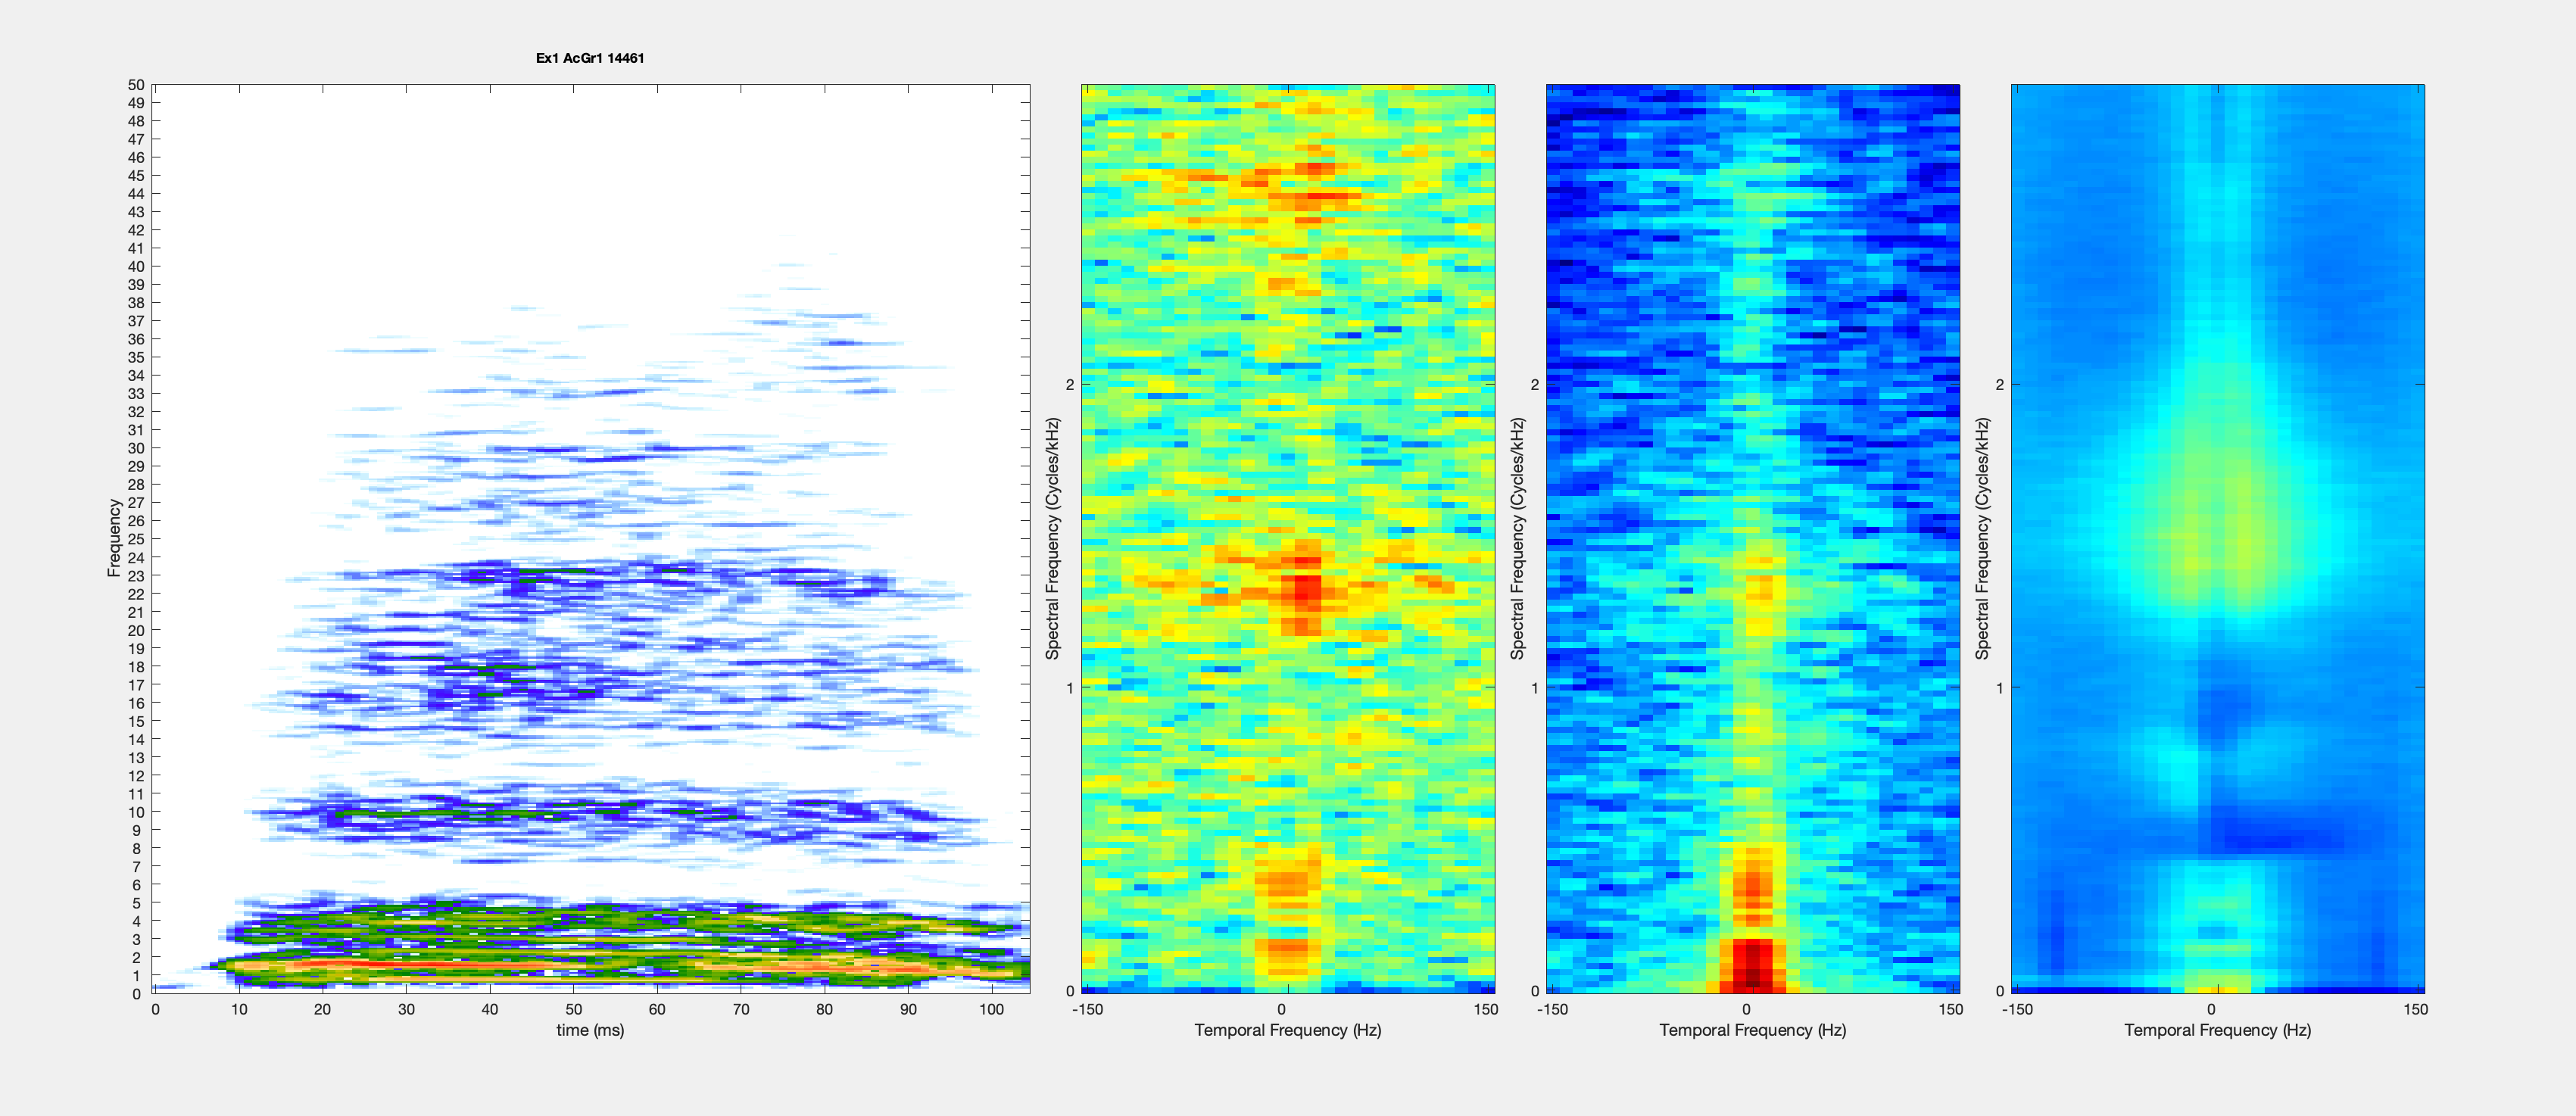

Ex1 AcGr1 14461


Ex2 AcGr1 65696
Ex3 AcGr1 14464
Ex4 AcGr1 14461
Ex5 AcGr1 14461
Ex1 AcGr2 14461
Ex2 AcGr2 71353
Ex3 AcGr2 65696
Ex4 AcGr2 14461
Ex5 AcGr2 65696
Ex1 AcGr3 14461
Ex2 AcGr3 71353
Ex3 AcGr3 14461
Ex4 AcGr3 65696
Ex5 AcGr3 14464
Ex1 AcGr4 14461
Ex2 AcGr4 14461
Ex3 AcGr4 11648
Ex4 AcGr4 14461
Ex5 AcGr4 11648
Ex1 AcGr5 14461
Ex2 AcGr5 14461
Ex3 AcGr5 14464
Ex4 AcGr5 14464
Ex5 AcGr5 14464
Ex1 AcGr6 14461
Ex2 AcGr6 14461
Ex3 AcGr6 71353
Ex4 AcGr6 11648
Ex5 AcGr6 14461
Ex1 AcGr7 14461
Ex2 AcGr7 11648
Ex3 AcGr7 11648
Ex4 AcGr7 71353
Ex5 AcGr7 11648


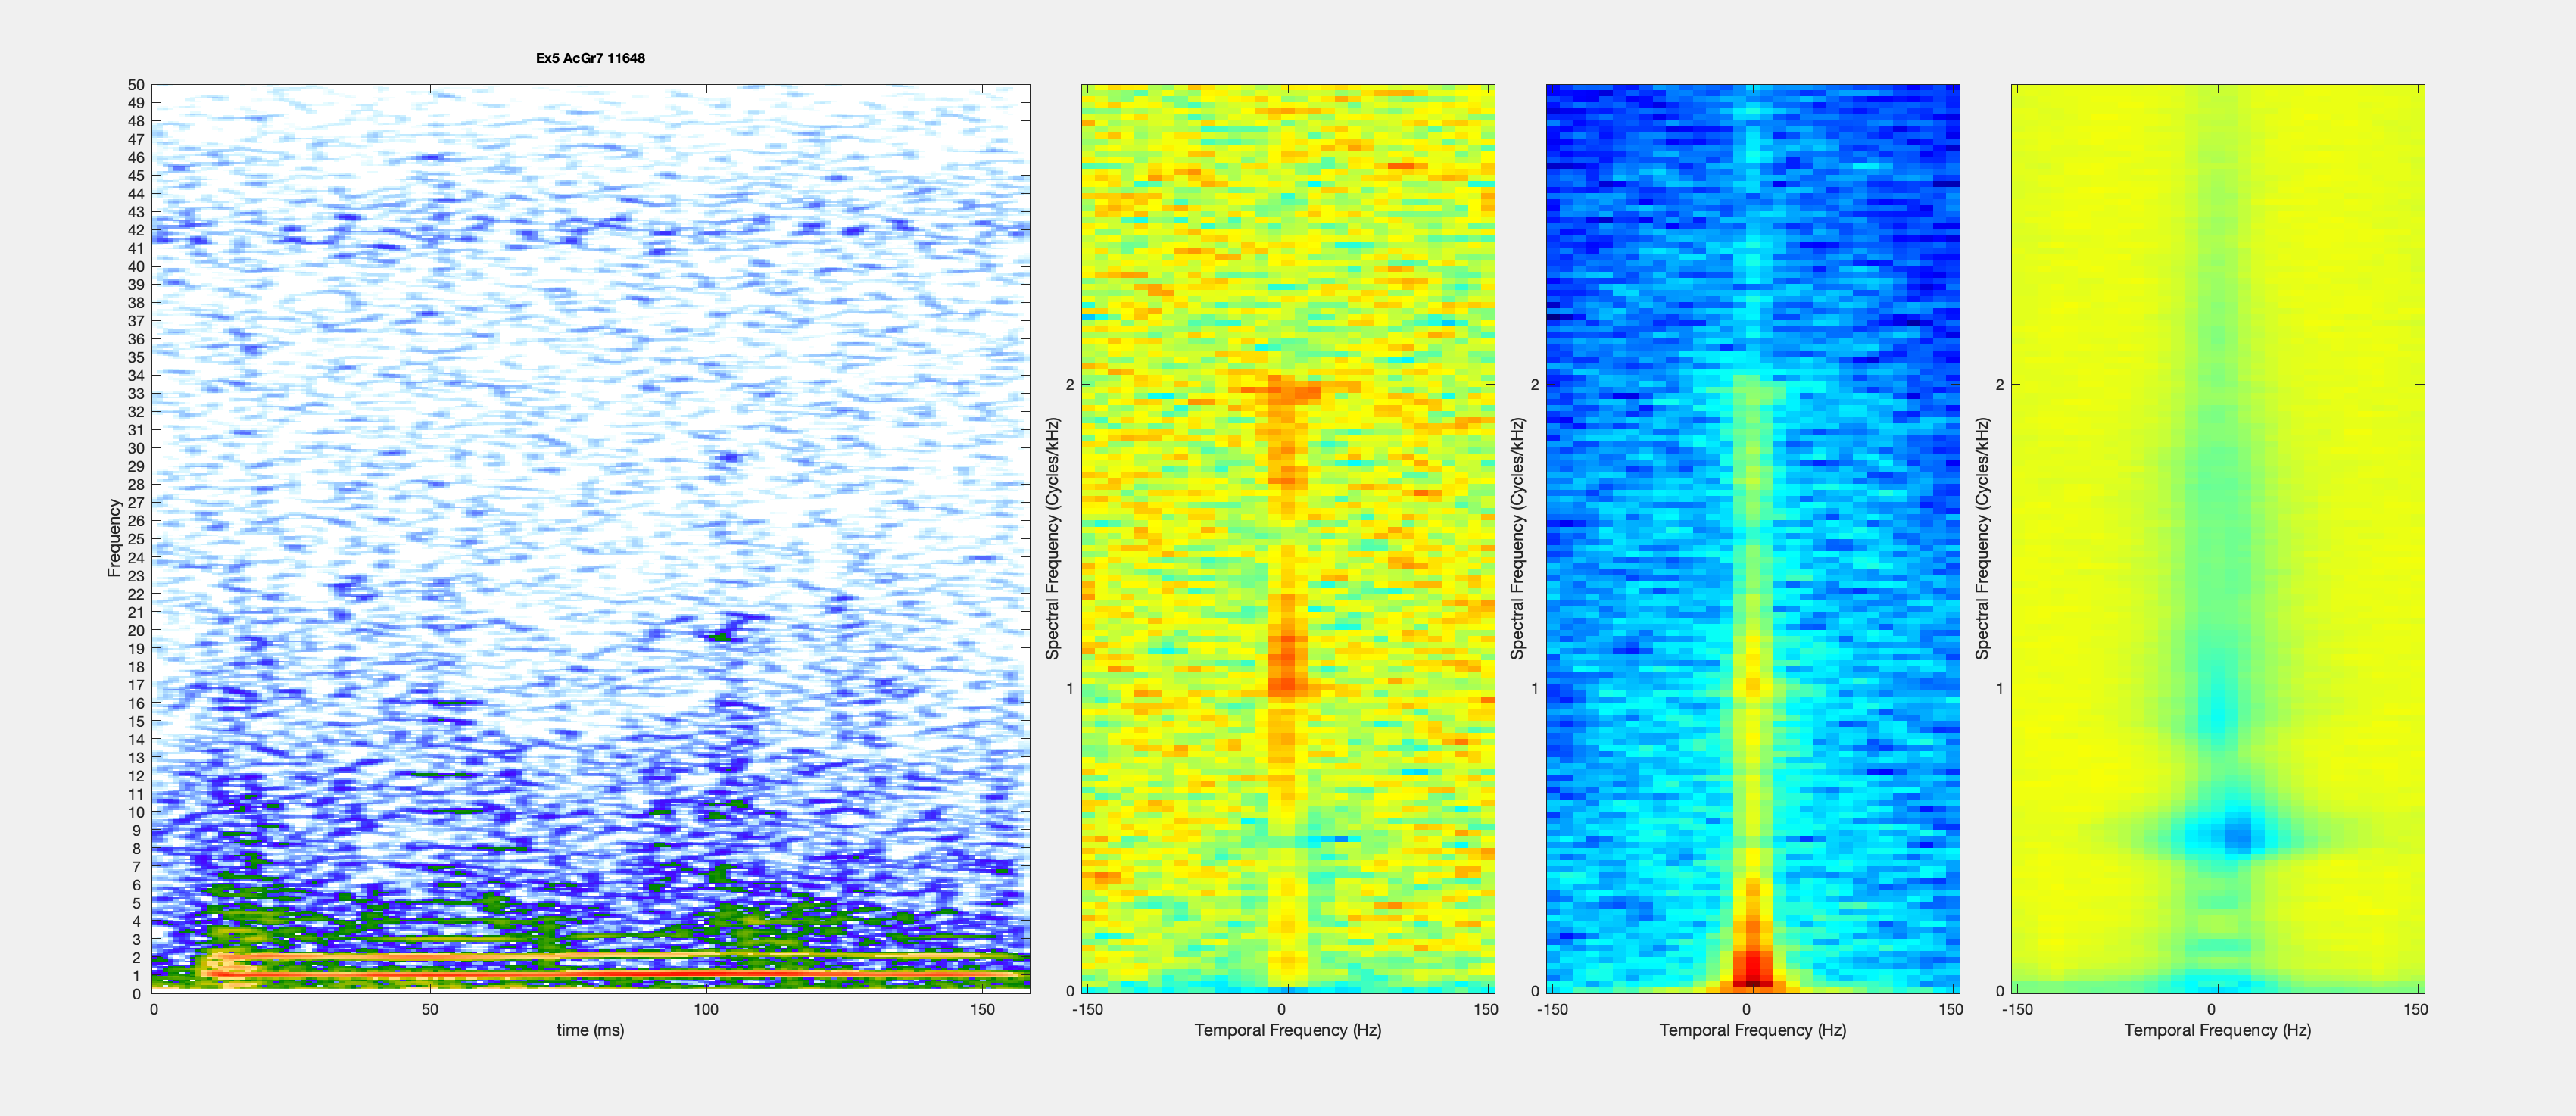

Fig1=figure(1);
clf
set(gcf,'Visible','on')
% T=tiledlayout(9,16,'TileSpacing','compact');

DBNOISE =50;
f_low = 0;
F_high = 50000; % max frequency used to calculate the spectrogram = 50kHz

% Identify the duration of all calls
Dur = nan(NumEx,length(UAC));
for GR=1:length(UAC)
    for ii=1:NumEx
        Dur(ii,UAC(GR)) = size(Example.(sprintf('H%d',UAC(GR))).Spectro{ii},2);
    end
end
MaxDur = max(max(Dur));

% Loop through examples and plot the spectrogram and the MPS
SpectroInd = 1:4:144;
MPS1Ind = SpectroInd+2;
MPS2Ind = SpectroInd+3;
CLim1 = cell(length(UAC),NumEx);
CLim2 = cell(length(UAC),NumEx);
for GR=1:length(UAC)
    for ii=1:NumEx
        Fig1=figure(1);
        clf
        T=tiledlayout(1,5,'TileSpacing','compact');
        N = nexttile(1,[1,2]);
%         N=nexttile(SpectroInd(ii + (GR-1)*NumEx), [1,2]);
        
        % plot the spectro
        logB = Example.(sprintf('H%d',UAC(GR))).Spectro{ii};
        maxB = max(max(logB));
        minB = maxB-DBNOISE;
%         if size(logB,2)<MaxDur % Set all spectrogram windows to be the same size
%             Before = ceil((MaxDur-size(logB,2))/2);
%             After = MaxDur-size(logB,2) - Before;
%             logB = [minB.*ones(size(logB,1),Before) logB minB.*ones(size(logB,1),After)];
%             To = [1:Before (Before + Example.(sprintf('H%d',UAC(GR))).To{ii}*1000) (Before + Example.(sprintf('H%d',UAC(GR))).To{ii}(end)*1000 + (1:After))];
%         else
%             To = Example.(sprintf('H%d',UAC(GR))).To{ii}*1000;
%         end
        To = Example.(sprintf('H%d',UAC(GR))).To{ii}*1000;
        IM=imagesc(To,Example.(sprintf('H%d',UAC(GR))).Fo{ii},logB);          % to is in seconds
        axis xy;
        caxis('manual');
        caxis([minB maxB]);
        cmap = spec_cmap();
        colormap(IM.Parent, cmap);
        v_axis = axis;
        v_axis(3)=f_low;
        v_axis(4)=F_high;
        axis(v_axis);
            xlabel('time (ms)')
            ylabel('Frequency');
            set(N,'YTick',0:1000:F_high,'YTickLabel',0:1:F_high/10^3)
%         set(N,'YTick',[],'YTickLabel',{})
        title(sprintf('Ex%d AcGr%d %s\n', ii,UAC(GR), Example.(sprintf('H%d',UAC(GR))).BatID{ii}), 'FontSize',9)
        fprintf(1,'Ex%d AcGr%d %s\n', ii,UAC(GR), Example.(sprintf('H%d',UAC(GR))).BatID{ii})
        % plot the average MPS of the Ac grp
        N=nexttile(3, [1 1]);
%         N=nexttile(MPS1Ind(ii + (GR-1)*NumEx), [1 1]);
        [CLim1{GR,ii}, Im2,~]=plot_mps(Example.(sprintf('H%d',UAC(GR))).MPS_norm{ii}, Example.(sprintf('H%d',UAC(GR))).Wf{ii}, Example.(sprintf('H%d',UAC(GR))).Wt{ii}, 60, [-22 16], 1, [0 max(Example.(sprintf('H%d',UAC(GR))).Wf{ii}*10^3)],[-150 150]);
%     xlabel('')
%     ylabel('')
%     xticklabels('')
%     yticklabels('')
%     N.FontSize = 8;
        % plot the normalized MPS
        N=nexttile(4, [1 1]);
%         N=nexttile(MPS2Ind(ii + (GR-1)*NumEx), [1 1]);
%         [CLim2{GR,ii},Im3,~]=plot_mps(MPSAcGr{GR}, Example.(sprintf('H%d',UAC(GR))).Wf{ii}, Example.(sprintf('H%d',UAC(GR))).Wt{ii}, 60, [-7.2 8.4], 1, [0 max(Example.(sprintf('H%d',UAC(GR))).Wf{ii}*10^3)],[-150 150]);
        [CLim2{GR,ii},Im3,~]=plot_mps(Example.(sprintf('H%d',UAC(GR))).MPS{ii}, Example.(sprintf('H%d',UAC(GR))).Wf{ii}, Example.(sprintf('H%d',UAC(GR))).Wt{ii}, 60, nan, 1, [0 max(Example.(sprintf('H%d',UAC(GR))).Wf{ii}*10^3)],[-150 150]);
        N=nexttile(5, [1 1]);
        [CLim2{GR,ii},Im3,~]=plot_mps(MPSAcGr{GR}, Example.(sprintf('H%d',UAC(GR))).Wf{ii}, Example.(sprintf('H%d',UAC(GR))).Wt{ii}, 60, [-7.2 8.4], 1, [0 max(Example.(sprintf('H%d',UAC(GR))).Wf{ii}*10^3)],[-150 150]);
        Audio = [zeros(1,192000/2) Example.(sprintf('H%d',UAC(GR))).Sound{ii} zeros(1,192000/2)];
        AP=audioplayer(Audio./(max(abs(Audio))),192000);
        play(AP)
        pause()
    end
end

Preferred examples for final figure:

Gr1: 1,**2*, 3*** Barks/ BuzzBarks

Gr2: **1*,3***,4 short noisy no pitch energy below 5kHz

Gr3: 1, **2*, 5*** noisy temporal structure low tucks repetitive energy up to 20kHz

Gr4: **2*,3***,4,5 very very short pips (10-20 ms), 2-3 harmonics, energy below 5kHz

Gr5: 1,2,**3*,5*** long high pitch dow sweep calls

Gr6: **3***,4,**5*** highly temporal buzz energy up to 15 kHz

Gr7: 1,**2*,3***,5 short pips with only 1-2 harmonics (10-20ms)energy below 5 kHz

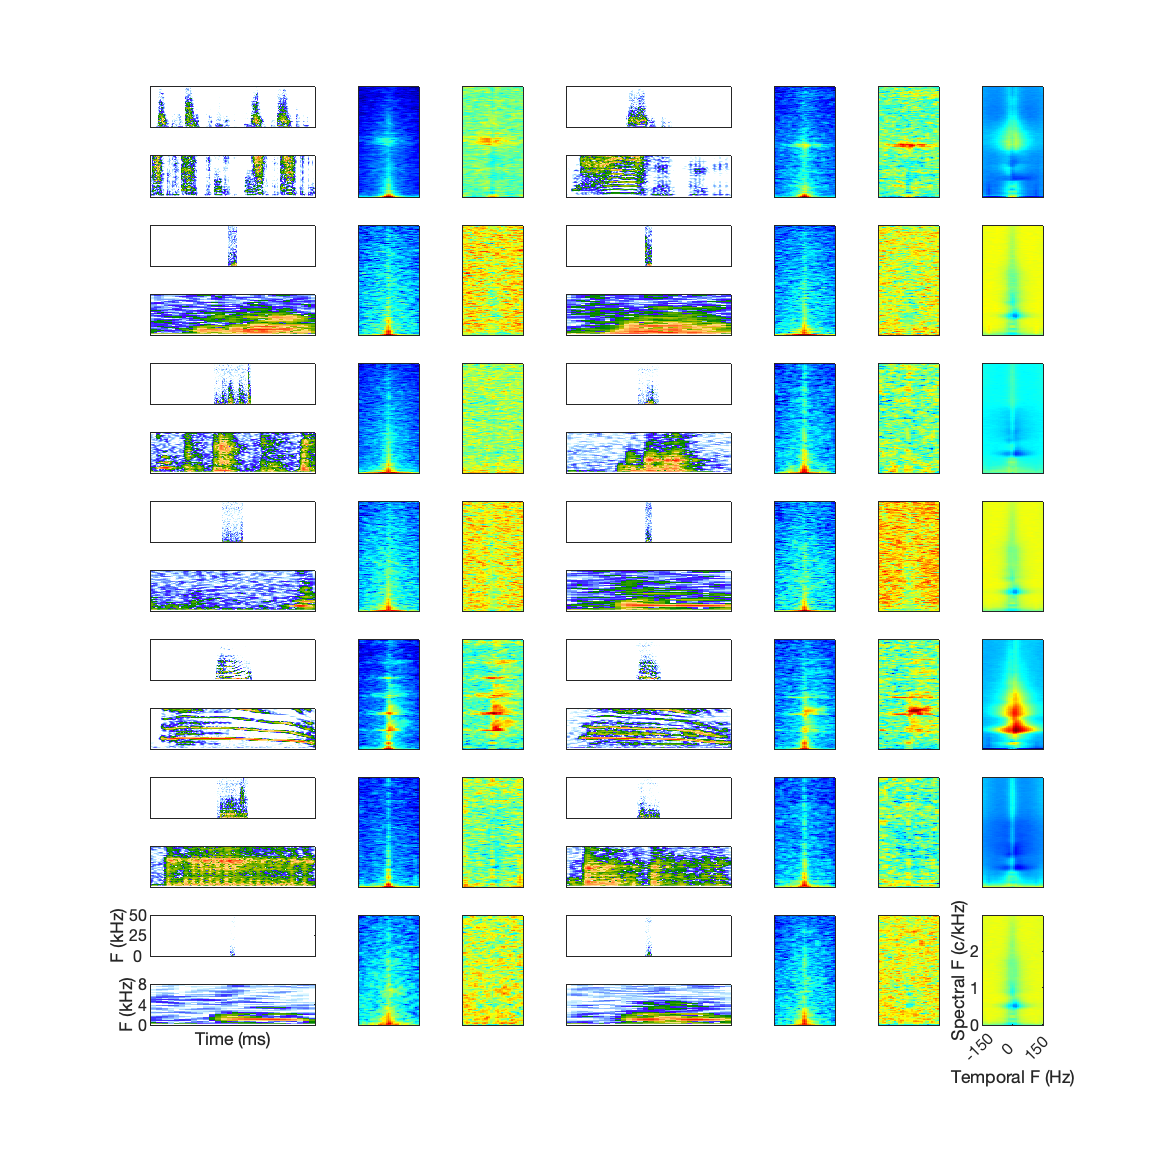

exid = 2

Ex1 AcGr1 65696


exid = 3

Ex2 AcGr1 14464


exid = 1

Ex1 AcGr2 14461


exid = 3

Ex2 AcGr2 65696


exid = 2

Ex1 AcGr3 71353


exid = 5

Ex2 AcGr3 14464


exid = 2

Ex1 AcGr4 14461


exid = 3

Ex2 AcGr4 11648


exid = 3

Ex1 AcGr5 14464


exid = 5

Ex2 AcGr5 14464


exid = 3

Ex1 AcGr6 71353


exid = 5

Ex2 AcGr6 14461


exid = 2

Ex1 AcGr7 11648


exid = 3

Ex2 AcGr7 11648


IndEx = [2 3; 1 3; 2 5; 2 3; 3 5; 3 5; 2 3];
Fig1=figure(1);
clf
set(gcf,'Visible','on')
T=tiledlayout(14,9,'TileSpacing','compact');

DBNOISE =50;
f_low = 0;
F_highhigh = 50000; % max frequency used to calculate the spectrogram = 50kHz
F_highlow = 8000; % max frequency used to calculate the spectrogram = 50kHz

% Identify the duration of all calls
Dur = nan(2,length(UAC));
for GR=1:length(UAC)
    for ii=1:2
        Dur(ii,UAC(GR)) = size(Example.(sprintf('H%d',UAC(GR))).Spectro{IndEx(UAC(GR),ii)},2);
    end
end
% MaxDur = max(max(Dur));
MaxDur = 800;

% Loop through examples and plot the spectrogram and the MPS
SpectroInd = sort([1:9:(13*9+1) (4+ (1:9:(13*9+1)))]);
MPS1Ind = sort([3:18:(14*18) (3:18:(14*18))+4]);
MPS2Ind = MPS1Ind +1;
MPS3Ind = 9:18:18*7;
CLim1 = cell(length(UAC),2);
CLim2 = cell(length(UAC),2);
for GR=1:length(UAC)
    for ii=1:2
        exid = IndEx(UAC(GR),ii)%% populate!!!
        N=nexttile(SpectroInd(ii + (GR-1)*4), [1,2]);
        % plot the spectro up to max frequency (50kHz)
        logB = Example.(sprintf('H%d',UAC(GR))).Spectro{exid};
        maxB = max(max(logB));
        minB = maxB-DBNOISE;
        if size(logB,2)<MaxDur % Set all spectrogram windows to be the same size
            Before = ceil((MaxDur-size(logB,2))/2);
            After = MaxDur-size(logB,2) - Before;
            logB2 = [minB.*ones(size(logB,1),Before) logB minB.*ones(size(logB,1),After)];
            To = [1:Before (Before + Example.(sprintf('H%d',UAC(GR))).To{exid}*1000) (Before + Example.(sprintf('H%d',UAC(GR))).To{exid}(end)*1000 + (1:After))];
        else
            logB2=logB;
            To = Example.(sprintf('H%d',UAC(GR))).To{exid}*1000;
        end
%         To = Example.(sprintf('H%d',UAC(GR))).To{ii}*1000;
        IM=imagesc(To,Example.(sprintf('H%d',UAC(GR))).Fo{exid},logB2);          % to is in seconds
        axis xy;
        caxis('manual');
        caxis([minB maxB]);
        cmap = spec_cmap();
        colormap(IM.Parent, cmap);
        v_axis = axis;
        v_axis(3)=f_low;
        v_axis(4)=F_highhigh;
        axis(v_axis);
%             
        if SpectroInd(ii + (GR-1)*4)==109
            set(N,'YTick',0:25000:F_highhigh,'YTickLabel',0:25:F_highhigh/10^3)
            ylabel('F (kHz)');
            set(N,'XTick',[],'XTickLabel',{})
            N.FontSize = 8;
        else
            set(N,'YTick',[],'YTickLabel',{})
            set(N,'XTick',[],'XTickLabel',{})
        end
%         title(sprintf('Ex%d AcGr%d %s\n', ii,UAC(GR), Example.(sprintf('H%d',UAC(GR))).BatID{exid}), 'FontSize',9)
        fprintf(1,'Ex%d AcGr%d %s\n', ii,UAC(GR), Example.(sprintf('H%d',UAC(GR))).BatID{exid})
        
        N=nexttile(SpectroInd(ii + (GR-1)*4 +2), [1,2]);
        % plot the spectro up to reduced frequency and zoom in time to just
        % the call
        IM=imagesc(Example.(sprintf('H%d',UAC(GR))).To{exid}*1000,Example.(sprintf('H%d',UAC(GR))).Fo{exid},logB);          % to is in seconds
        axis xy;
        caxis('manual');
        caxis([minB maxB]);
        cmap = spec_cmap();
        colormap(IM.Parent, cmap);
        v_axis = axis;
        v_axis(3)=f_low;
        v_axis(4)=F_highlow;
        axis(v_axis);
        if SpectroInd(ii + (GR-1)*4+2)==118
            set(N,'YTick',0:F_highlow/2:F_highlow,'YTickLabel',(0:F_highlow/2:F_highlow)/10^3)
            xlabel('Time (ms)')
            ylabel('F (kHz)');
            set(N,'XTick',[],'XTickLabel',{})
            N.FontSize = 8;
        else
            set(N,'YTick',[],'YTickLabel',{})
            N.YLabel.String = '';
            set(N,'XTick',[],'XTickLabel',{})
            N.XLabel.String = '';
        end
        
        % plot the MPS
        N=nexttile(MPS1Ind(ii + (GR-1)*2), [2 1]);
        [CLim1{GR,ii},Im1,~]=plot_mps(Example.(sprintf('H%d',UAC(GR))).MPS{exid}, Example.(sprintf('H%d',UAC(GR))).Wf{exid}, Example.(sprintf('H%d',UAC(GR))).Wt{exid}, 60, nan, 1, [0 max(Example.(sprintf('H%d',UAC(GR))).Wf{exid}*10^3)],[-150 150]);
%         if MPS1Ind(ii + (GR-1)*2)==237
%             ylabel('Spectral F (c/kHz)')
%             xlabel('Temporal F (Hz)')
%         else
            set(N,'YTick',[],'YTickLabel',{})
            N.YLabel.String = '';
            set(N,'XTick',[],'XTickLabel',{})
            N.XLabel.String = '';
%         end
        % plot the normalized MPS
        N=nexttile(MPS2Ind(ii + (GR-1)*2), [2 1]);
        [CLim2{GR,ii}, Im2,~]=plot_mps(Example.(sprintf('H%d',UAC(GR))).MPS_norm{exid}, Example.(sprintf('H%d',UAC(GR))).Wf{exid}, Example.(sprintf('H%d',UAC(GR))).Wt{exid}, 60, [-22 16], 1, [0 max(Example.(sprintf('H%d',UAC(GR))).Wf{exid}*10^3)],[-150 150]);
%         if MPS2Ind(ii + (GR-1)*2)==238
%             ylabel('Spectral F (c/kHz)')
%                 xlabel('Temporal F (Hz)')
%         else
            set(N,'YTick',[],'YTickLabel',{})
            N.YLabel.String = '';
            set(N,'XTick',[],'XTickLabel',{})
            N.XLabel.String = '';
%         end
        %     xlabel('')
%     ylabel('')
%     xticklabels('')
%     yticklabels('')
%     N.FontSize = 8;
        
%         N=nexttile(4, [1 1]);
%         N=nexttile(MPS2Ind(ii + (GR-1)*NumEx), [1 1]);
        
        % plot the average MPS of the Ac grp
        if ii==2
            N=nexttile(MPS3Ind(GR), [2 1]);
            [CLim3{GR,ii},Im3,~]=plot_mps(MPSAcGr{GR}, Example.(sprintf('H%d',UAC(GR))).Wf{exid}, Example.(sprintf('H%d',UAC(GR))).Wt{exid}, 60, [-7.2 8.4], 1, [0 max(Example.(sprintf('H%d',UAC(GR))).Wf{exid}*10^3)],[-150 150]);
            if GR==7
                ylabel('Spectral F (c/kHz)')
                xlabel('Temporal F (Hz)')
                N.FontSize = 8;
            else
                set(N,'YTick',[],'YTickLabel',{})
                N.YLabel.String = '';
                set(N,'XTick',[],'XTickLabel',{})
                N.XLabel.String = '';
            end
        end
        
        Audio = [zeros(1,192000/2) Example.(sprintf('H%d',UAC(GR))).Sound{exid} zeros(1,192000/2)];
        AP=audioplayer(Audio./(max(abs(Audio))),192000);
        play(AP)
        pause()
        audiowrite(fullfile(Path2Paper,sprintf('AcousticGroup%d_Example%d_Bat%s.wav', UAC(GR),ii, Example.(sprintf('H%d',UAC(GR))).BatID{exid})),Audio,192000);
    end
end



Fig1.PaperOrientation = 'landscape';
Fig1.Units = 'inches';
Fig1.Position(3:4) = [8 8];
Fig1.PaperSize = [8 8];
print(Fig1,fullfile(Path2Paper,'SupFigure2_CallExamples.pdf'),'-dpdf','-fillpage')

function [Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(VARcol,x, MinColVal, MaxColVal)
% Getting VARZ ready for plotting.
% If VARcol is always a non-null
% integer then you can use it directly in cubehelix by specifying x=1
% otherwise, the function first multiplies VARcol by 10^x to make sure its
% variability is maximized after ceiling it to an integer
if nargin<2
    x=3;% here I'm doing *1000 as an example
end

if nargin<3
    MinColVal=0;
end

if nargin<4
    MaxColVal = max(VARcol);
end

%     if nargin<5
%         LogToggle=0;
%     end
% Make sure you don't have nan values
VARcol = VARcol(~isnan(VARcol));
%     if LogToggle==2
%         VARcol = log2(VARcol);
%     elseif LogToggle==10
%         VARcol = log10(VARcol);
%     end


% Scale your minimum value as 0 or min Val
Slide = 0;
if ~MinColVal && sum(VARcol<=0)>0
    Slide = -min(VARcol)+ 10^(-x);
elseif MinColVal==1
    Slide = -min(VARcol)+ 10^(-x);
elseif MinColVal
    Slide = -MinColVal+ 10^(-x);
end

VARcol_cube = ceil((VARcol+Slide)*10^x);
%GRAD=cubehelix(max(VARZ_cube));%Note that you can choose the values of...
...your gradient by doing cubehelix_view and then specifying the values in...
    ...the function, for instance: GRAD=cubehelix(max(VARZ_cube),0.5, -0.8, 1.5, 1.7, [1,0]);
    %     GRAD=cubehelix(max(VARcol_cube),0.5, -1.1, 1.5, 0.5, [1,0]);
%     GRAD=cubehelix(max(VARcol_cube),0.5, -0.8, 1.5, 1.7, [1,0]);
GRAD=cubehelix(ceil((MaxColVal+Slide)*10^x),0.5, -1.5, 1, 1, [1,0]);

NU = length(VARcol_cube); % this is the number of points you have in your plot
Colors = nan(NU, size(GRAD,2));
for jj=1:NU
    Colors(jj,:) = GRAD(VARcol_cube(jj),:); % for each dot you call the line in the gradient of color that correspond to the value in Z
end

% figure()
%
%     cc=colorbar();
%     colormap(GRAD)
%     set(gca, 'Color', [0.7 0.7 0.7])
%
%     YTL = get(cc, 'YTickLabel');
%     YTL_new = ceil((MaxColVal+Slide)*10^x) .* str2double(YTL)/10^x - Slide;
%     if LogToggle==2
%         YTL_new = 2.^YTL_new;
%     elseif LogToggle==10
%         YTL_new = 10.^YTL_new;
%     end
%     YTL_new = num2str(round(YTL_new.*10^(x-1))./10^(x-1));
%     set(cc, 'YTickLabel',YTL_new)%here you correct the value of the z axis that you artificially multiplied by 10^x

end


function [CLim,Im,MPS4plot, Wt_local, Wf_local]=plot_mps(MPS, Wf, Wt, DBNOISE,CLim,Log, YLim, XLim, TwoDfilter)
%[CB,Im,MPS4plot, Wt_local, Wf_local]=plot_mps(MPS, Wf, Wt, DBNOISE,CLim,Log, YLim, XLim, TwoDfilter)
if nargin<4
    DBNOISE=60;
end

if nargin<6
    Log=1;
end

if nargin<7
    YLim = [0 max(Wf*10^3)];
end
if nargin<8
    XLim = [min(Wt) max(Wt)];
end
if nargin<5
    CLim = nan;
end
if nargin<9
    TwoDfilter=0;
end

Wf_i = logical((Wf*10^3>=YLim(1)).* (Wf*10^3<=YLim(2)));
Wt_i = logical((Wt>=XLim(1)).* (Wt<=XLim(2)));
MPS = MPS(Wf_i, Wt_i);
Wf_local = Wf(Wf_i);
Wt_local = Wt(Wt_i);
if Log
    MPS4plot = 10*log10(MPS);
else
    MPS4plot = MPS;
end
MaxMPS = max(max(MPS4plot));
MinMPS = MaxMPS-DBNOISE;
MPS4plot(MPS4plot < MinMPS) = MinMPS;

if TwoDfilter
    MPS4plot = imgaussfilt(MPS4plot,TwoDfilter);
end

%             imagesc(LogMPS, interpolation='nearest', aspect='auto', origin='lower', cmap=cmap, extent=ex)
Im = imagesc(MPS4plot);
axis xy
colormap(Im.Parent,'jet');
% CB=colorbar();
%     CB.YTick=0;
%     CB.YTickLabel=0;
%     CB.Units = 'inches';
%     CB.Location='north';
%     CB.Position(4) = 0.1;
%     CB.Position(2) = CB.Position(2) + 0.2;
% CB.Label.String = 'Power (dB)';
xlabel('Temporal Frequency (Hz)')
ylabel('Spectral Frequency (Cycles/kHz)')
% get nice X and y tick labels
MaxWf = max(floor(Wf_local*10^3));
YTickLabel=0:MaxWf;
YTick = nan(length(YTickLabel),1);
for yy=1:length(YTick)
    YTick(yy) = find(floor(Wf_local*10^3)==YTickLabel(yy),1);
end
set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
MaxWt = max(ceil(Wt_local*10^-1))*10^1;
XTickLabel = [-MaxWt 0 MaxWt];
XTick = nan(length(XTickLabel),1);
for xx=1:length(XTick)
    [~,XTick(xx)] = min(abs(round(Wt_local)-XTickLabel(xx)));
end
set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
if ~isnan(CLim)
    PlotMPS = gca;
    PlotMPS.CLim = CLim;
else
    PlotMPS = gca;
    CLim = PlotMPS.CLim;
end
end

function [MPS4plot, Wt_local, Wf_local]=plot_mps_original(MPS, Wf, Wt, DBNOISE,CLim,Log, YLim, XLim, TwoDfilter)
if nargin<4
    DBNOISE=60;
end

if nargin<6
    Log=1;
end

if nargin<7
    YLim = [0 max(Wf*10^3)];
end
if nargin<8
    XLim = [min(Wt) max(Wt)];
end
if nargin<5
    CLim = nan;
end
if nargin<9
    TwoDfilter=0;
end

Wf_i = logical((Wf*10^3>=YLim(1)).* (Wf*10^3<=YLim(2)));
Wt_i = logical((Wt>=XLim(1)).* (Wt<=XLim(2)));
MPS = MPS(Wf_i, Wt_i);
Wf_local = Wf(Wf_i);
Wt_local = Wt(Wt_i);
if Log
    MPS4plot = 10*log10(MPS);
    MaxMPS = max(max(MPS4plot));
    MinMPS = MaxMPS-DBNOISE;
    MPS4plot(MPS4plot < MinMPS) = MinMPS;
else
    MPS4plot = MPS;
end

if TwoDfilter
    MPS4plot = imgaussfilt(MPS4plot,TwoDfilter);
end

%             imagesc(LogMPS, interpolation='nearest', aspect='auto', origin='lower', cmap=cmap, extent=ex)
Im = imagesc(MPS4plot);
axis xy
colormap(Im.Parent,'jet');
c=colorbar();
c.Label.String = 'Power (dB)';
xlabel('Temporal Frequency (Hz)')
ylabel('Spectral Frequency (Cycles/kHz)')
% get nice X and y tick labels
MaxWf = max(floor(Wf_local*10^3));
YTickLabel=0:MaxWf;
YTick = nan(length(YTickLabel),1);
for yy=1:length(YTick)
    YTick(yy) = find(floor(Wf_local*10^3)==YTickLabel(yy),1);
end
set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
MaxWt = max(floor(Wt_local*10^-2))*10^2;
XTickLabel = -MaxWt:100:MaxWt;
XTick = nan(length(XTickLabel),1);
for xx=1:length(XTick)
    [~,XTick(xx)] = min(abs(round(Wt_local)-XTickLabel(xx)));
end
set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
if ~isnan(CLim)
    PlotMPS = gca;
    PlotMPS.CLim = CLim;
end
end